phase = -0.25;
t = linspace(0, 10, 500);
noise = rand(1,500)*3;
sig = (t+phase - round(t+phase))*2 + noise;
sinn = sin(3 * pi * t);
coss = cos(3 * pi * t);

f1 = sig .* sinn;
g1 = sig .* coss;

% figure
% hold on
% plot(abs(fftshift(fft(sig, 500))))
% plot(abs(fftshift(fft(sinn, 500))))
% plot(abs(fftshift(fft(f1, 500))))
% plot(abs(fftshift(fft(g1, 500))))

% figure
% hold on
% plot(abs(fft(sig, 500)))
% plot(abs(fft(sinn, 500)))
% plot(abs(fft(f1, 500)))
% plot(abs(fft(g1, 500)))
% xlim([0 250])

figure
hold on
plot(real(ifft(fft(sig, 500))))
% plot(real(ifft(fft(sinn, 500))))
lockin = fft(f1, 500);
lockin(7:end-7) = 0;
lockin = real(ifft(lockin));
l = mean(lockin)

l = 0.0195

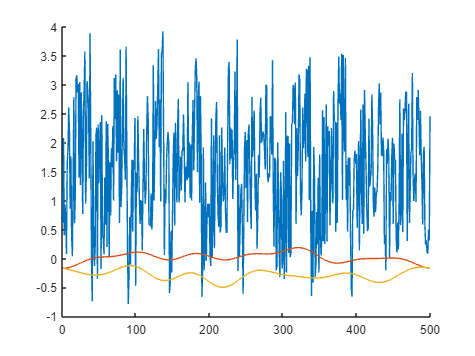

plot(lockin)
lockinA = fft(g1, 500);
lockinA(7:end-7) = 0;
lockinA = real(ifft(lockinA));
plot(lockinA)

lA = mean(lockinA)

lA = -0.2847


disp(sqrt(l ^2 + lA ^2))

    0.2854

